# Post processing

## Read futek data

% should add out folder to matlab path
fds = fileDatastore('futek_data/experiment_*.txt', 'ReadFcn', @importdata);
fullFileNames = fds.Files;
% [pathstr, name, ext] = fileparts(fullFileNames{1})
numFiles = length(fullFileNames);
% Loop over all files reading them in and plotting them.
futek_data = cell(numFiles,2);
for k = 1 : numFiles

    fprintf('Now reading file %s\n', fullFileNames{k});
    A = import_futek_data(fullFileNames{k});
    if isempty(A) == false
        futek_data{k,1} = A;
        temp = strsplit(fullFileNames{k},"/");
        futek_data{k,2} = temp{end};
    end
end

Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_map_b.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_map_s.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_multiroll.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_press_b.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_press_s.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_rep_s1.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_rep_s2.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_rep_s3.txt
Now 

## Read velostat data

fds = fileDatastore('velostat_data/experiment_*.txt', 'ReadFcn', @importdata);
fullFileNames = fds.Files;
% [pathstr, name, ext] = fileparts(fullFileNames{1})
numFiles = length(fullFileNames);
% Loop over all files reading them in and plotting them.
velostat_data = cell(numFiles,2);
for k = 1 : numFiles

    fprintf('Now reading file %s\n', fullFileNames{k});
    A = import_velostat_data(fullFileNames{k});
    if isempty(A) == false
        velostat_data{k,1} = A;
        temp = strsplit(fullFileNames{k},"/");
        velostat_data{k,2} = temp{end};
    end
end

Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_map_b.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_map_s.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_multiroll.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_press_b.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_press_s.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_rep_s1.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_rep_s2.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data

## Calibrate velostat

fds = fileDatastore('velostat_data_for_calibration/experiment_*.txt', 'ReadFcn', @importdata);
fullFileNames = fds.Files;
% [pathstr, name, ext] = fileparts(fullFileNames{1})
numFiles = length(fullFileNames);
% Loop over all files reading them in and plotting them.
velostat_data_calibrated = cell(numFiles,2);
for k = 1 : numFiles

    fprintf('Now reading file %s\n', fullFileNames{k});
    A = calibrate_velostat_data(fullFileNames{k});
    if isempty(A) == false
        velostat_data_calibrated{k,1} = A;
        temp = strsplit(fullFileNames{k},"/");
        velostat_data_calibrated{k,2} = temp{end};
    end
end

Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration/experiment_0.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration/experiment_1.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration/experiment_10.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration/experiment_11.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration/experiment_12.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration/experiment_13.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration/experiment_14.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data_for_calibration/experiment_1

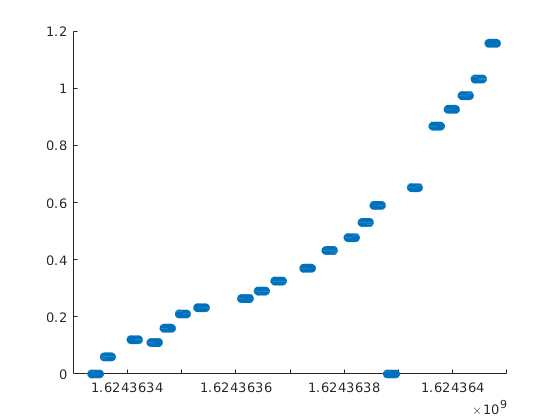


calibrate = cat(1,velostat_data_calibrated{:,1});
tim = cell2mat(calibrate(:,2));
vel = cell2mat(calibrate(:,1));
real = cell2mat(calibrate(:,3));

scatter(tim,real)

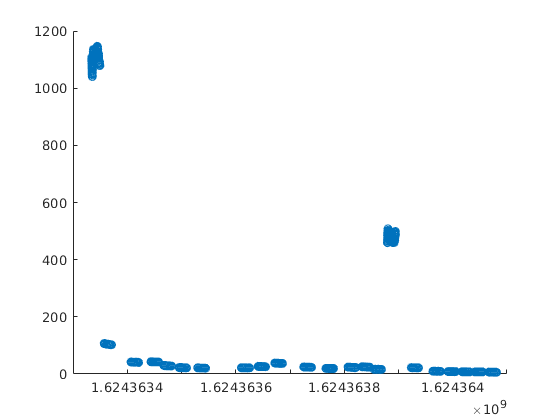

figure
scatter(tim,vel)

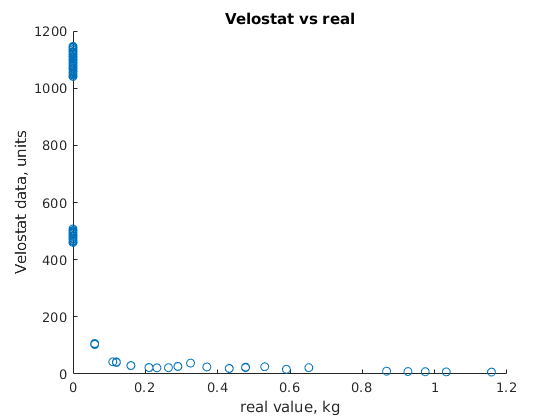

figure 
cur_plot = scatter(real,vel);
title("Velostat vs real");
xlabel("real value, kg");
ylabel("Velostat data, units");

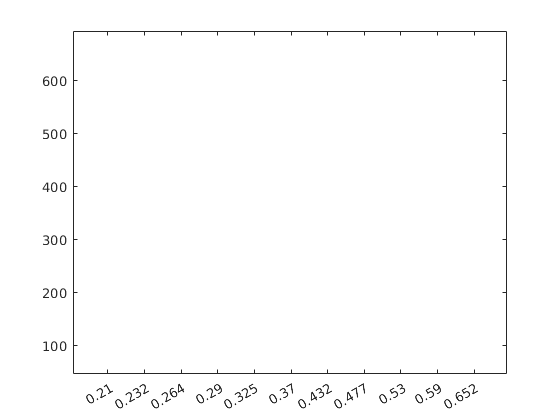

figure
boxplot(vel,real)
ylim([0 100])

figure
% autocorr(vel)
% corr(vel,real,'omitrows')

% cur_plot(1).LineWidth = 2;
% cur_plot(1).MarkerSize= 4;
% cur_plot(1).Marker = "*";
% velostat_data_calibrated = velostat_data;

## Exp 0 

num = (1:2);

exp0_futek_data = futek_data(num,:);

exp0_velostat_data = velostat_data(num,:);

exp0_title_name = "Experiment 0, testing: ";

needed_max = quantile(cell2mat(exp0_velostat_data{2,1}(:,1)),0.8);

temp_array = cell2mat(exp0_velostat_data{2,1}(:,:));

temp_array(temp_array(:,1)>needed_max,:) = [];

exp0_velostat_data{2,1} = mat2cell(temp_array,[size(temp_array,1),2]);

exp0_sensor_names = ["10 min","pikes"];

exp0_rmse = common_postproc_plots(exp0_futek_data,exp0_velostat_data, exp0_title_name, exp0_sensor_names);

## Experiment 1, repitability

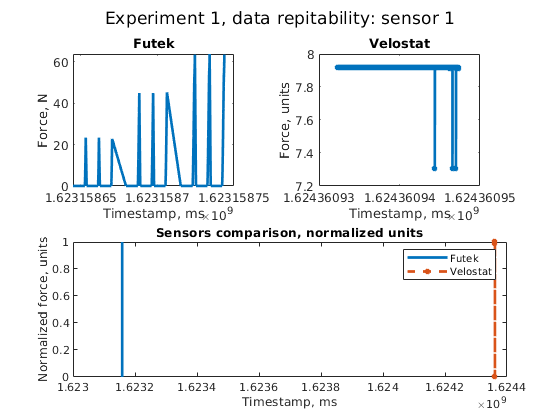

20 amount of futek peaks
4 amount of velostat peaks
Amount of peaks are not equal or equal to 0


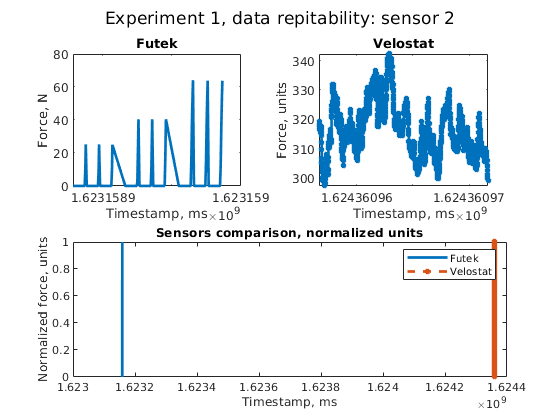

22 amount of futek peaks
34 amount of velostat peaks
Amount of peaks are not equal or equal to 0


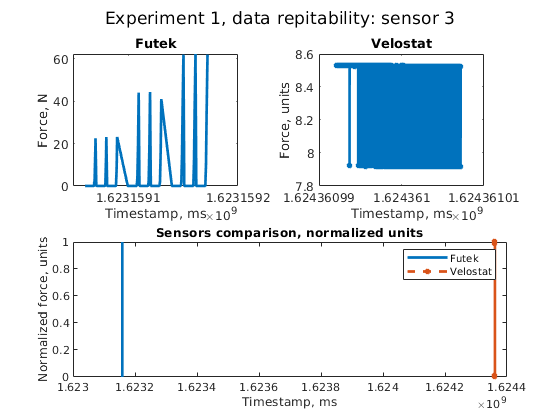

28 amount of futek peaks
34 amount of velostat peaks
Amount of peaks are not equal or equal to 0


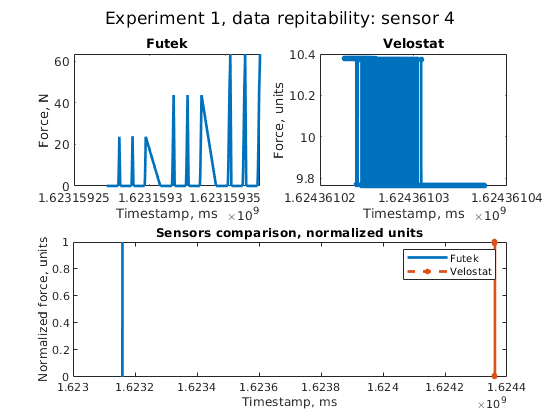

25 amount of futek peaks
18 amount of velostat peaks
Amount of peaks are not equal or equal to 0


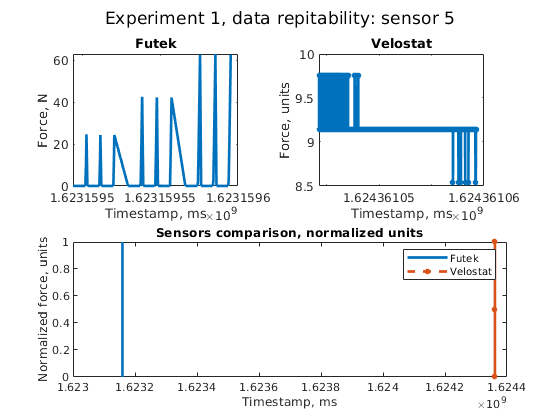

20 amount of futek peaks
13 amount of velostat peaks
Amount of peaks are not equal or equal to 0


num = (7:11);
exp1_futek_data = futek_data(num,:);
exp1_velostat_data = velostat_data_calibrated(num,:);
exp1_title_name = "Experiment 1, data repitability: ";
exp1_sensor_names = (1:5);
exp1_rmse = common_postproc_plots(exp1_futek_data,exp1_velostat_data, exp1_title_name, exp1_sensor_names);

## Experiment 2, pressure vs Force

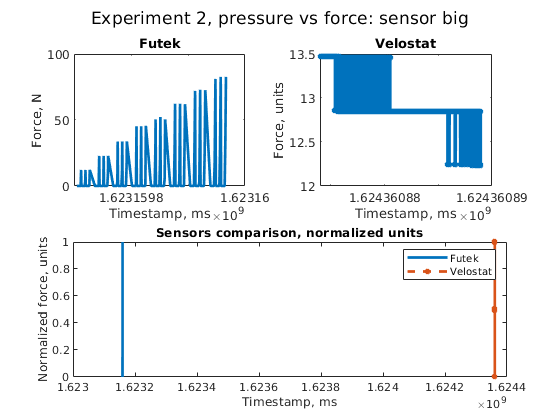

54 amount of futek peaks
22 amount of velostat peaks
Amount of peaks are not equal or equal to 0


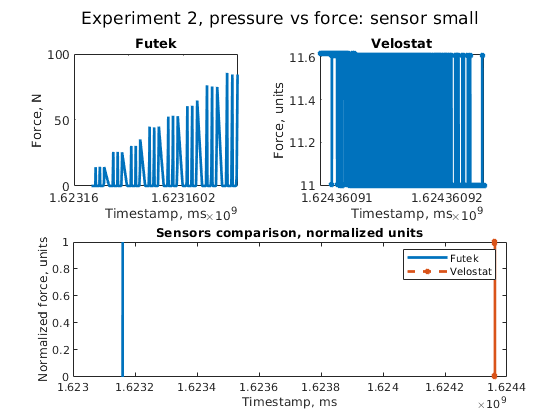

54 amount of futek peaks
34 amount of velostat peaks
Amount of peaks are not equal or equal to 0


num = (5:6);
exp2_futek_data = futek_data(num,:);
exp2_velostat_data = velostat_data_calibrated(num,:);
exp2_title_name = "Experiment 2, pressure vs force: ";
exp2_sensor_names = ["big", "small"];
exp2_rmse = common_postproc_plots(exp2_futek_data,exp2_velostat_data, exp2_title_name, exp2_sensor_names);

## Experiment 3, sensor force map

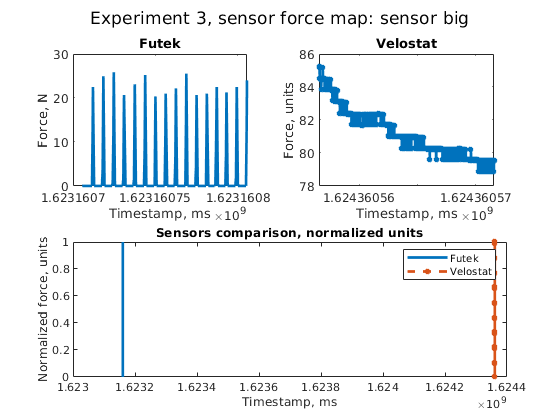

27 amount of futek peaks
38 amount of velostat peaks
Amount of peaks are not equal or equal to 0


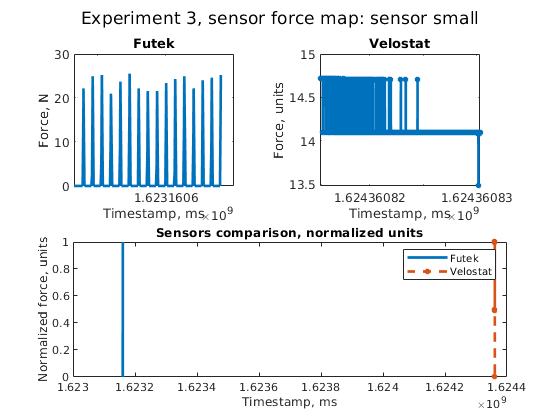

19 amount of futek peaks
20 amount of velostat peaks
Amount of peaks are not equal or equal to 0


num = (2:3);
exp3_futek_data = futek_data((num),:);
exp3_velostat_data = velostat_data_calibrated((num),:);
exp3_title_name = "Experiment 3, sensor force map: ";
exp3_sensor_names = ["big", "small"];
exp3_rmse = common_postproc_plots(exp3_futek_data,exp3_velostat_data, exp3_title_name, exp3_sensor_names);

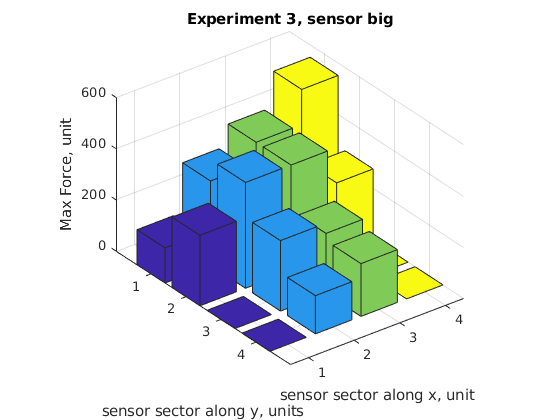


figure
Zb = [[137,330,413,551];[275,413,413,275];[0,275,235,0];[0,149,206,0]];
Zs = [[235,235,275,235];[126,183,149,164];[149,183,149,126];[96,91,126,126]];
bar3(Zb);
title("Experiment 3, sensor big");
xlabel("sensor sector along x, unit");
ylabel("sensor sector along y, units");
zlabel("Max Force, unit")

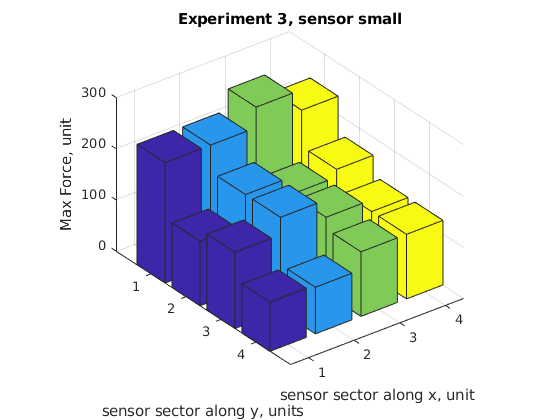

figure
bar3(Zs);
title("Experiment 3, sensor small");
xlabel("sensor sector along x, unit");
ylabel("sensor sector along y, units");
zlabel("Max Force, unit")


disp("TODO statistics")

TODO statistics


## Experiment 4, leg load simulation (rolling rolls)

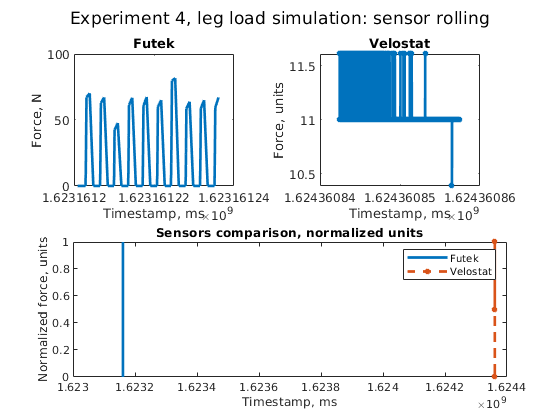

10 amount of futek peaks
22 amount of velostat peaks
Amount of peaks are not equal or equal to 0


num = (4);
exp4_futek_data = futek_data(num,:);
exp4_velostat_data = velostat_data_calibrated(num,:);
exp4_title_name = "Experiment 4, leg load simulation: ";
exp4_sensor_names = ["rolling"];
exp4_rmse = common_postproc_plots(exp4_futek_data,exp4_velostat_data, exp4_title_name, exp4_sensor_names);